function images = loadMNISTImages(filename)
    fid = fopen(filename, 'rb');

    magic = fread(fid, 1, 'int32', 0, 'ieee-be');
    numImages = fread(fid, 1, 'int32', 0, 'ieee-be');
    numRows = fread(fid, 1, 'int32', 0, 'ieee-be');
    numCols = fread(fid, 1, 'int32', 0, 'ieee-be');

    images = fread(fid, inf, 'unsigned char');
    fclose(fid);

    images = reshape(images, numCols * numRows, numImages);
    images = double(images) / 255;
end

function labels = loadMNISTLabels(filename)
    fid = fopen(filename, 'rb');

    magic = fread(fid, 1, 'int32', 0, 'ieee-be');
    numLabels = fread(fid, 1, 'int32', 0, 'ieee-be');

    labels = fread(fid, inf, 'unsigned char');
    fclose(fid);

    labels = double(labels);
end

X_train = loadMNISTImages("C:\Users\bhupa\Videos\train-images.idx3-ubyte");
y_train = loadMNISTLabels("C:\Users\bhupa\Videos\train-labels.idx1-ubyte");
X_test = loadMNISTImages("C:\Users\bhupa\Videos\t10k-images.idx3-ubyte");
y_test = loadMNISTLabels("C:\Users\bhupa\Videos\t10k-labels.idx1-ubyte");

function Y = oneHotEncode(y, numClasses)
    Y = zeros(numClasses, length(y));
    for i = 1:length(y)
        Y(y(i)+1, i) = 1;
    end
end

Y_train = oneHotEncode(y_train, 10);
Y_test  = oneHotEncode(y_test, 10);

# **Learning rate change to 1e-1**

d0 = 784; d1 = 128; d2 = 64; d3 = 10;
r1 = min(d1,d0);
r2 = min(d2,d1);
r3 = min(d3,d2);
rng(1);
[U1,~] = qr(randn(d1,r1),0);
[V1,~] = qr(randn(d0,r1),0);
alpha1 = randn(r1,1);
[U2,~] = qr(randn(d2,r2),0);
[V2,~] = qr(randn(d1,r2),0);
alpha2 = randn(r2,1);
[U3,~] = qr(randn(d3,r3),0);
[V3,~] = qr(randn(d2,r3),0);
alpha3 = randn(r3,1);

epochs = 100;
batch_size = 128;
lr = 1e-1;
lambda_orth = 1e-2;
lambda_sparse = 1e-3;
N = size(X_train,2);
num_batches = floor(N/batch_size);
loss_hist = zeros(epochs,1);

for epoch = 1:epochs
    perm = randperm(N);
    epoch_loss = 0;
    for b = 1:num_batches
        idx = perm((b-1)*batch_size+1 : b*batch_size);
        X = X_train(:,idx);
        Y = Y_train(:,idx);
        m = size(X,2);
        s1 = exp(alpha1);  S1 = diag(sqrt(s1));
        s2 = exp(alpha2);  S2 = diag(sqrt(s2));
        s3 = exp(alpha3);  S3 = diag(sqrt(s3));
        H1 = S1*(V1'*X);        Z1 = U1*S1*H1;  A1 = max(0,Z1);
        H2 = S2*(V2'*A1);       Z2 = U2*S2*H2;  A2 = max(0,Z2);
        H3 = S3*(V3'*A2);       Z3 = U3*S3*H3;
        Z3 = Z3 - max(Z3,[],1);
        Yhat = exp(Z3) ./ sum(exp(Z3),1);
        CE = -sum(sum(Y .* log(Yhat))) / m;
        Orth = ...
            norm(U1'*U1-eye(size(U1,2)),'fro')^2 + norm(V1'*V1-eye(size(V1,2)),'fro')^2 + ...
            norm(U2'*U2-eye(size(U2,2)),'fro')^2 + norm(V2'*V2-eye(size(V2,2)),'fro')^2 + ...
            norm(U3'*U3-eye(size(U3,2)),'fro')^2 + norm(V3'*V3-eye(size(V3,2)),'fro')^2;

        Sparse = norm(s1,1)/norm(s1,2) + norm(s2,1)/norm(s2,2) + norm(s3,1)/norm(s3,2);
        loss = CE + lambda_orth*Orth + lambda_sparse*Sparse;
        epoch_loss = epoch_loss + loss;
        dZ3 = Yhat - Y;
        dU3 = (dZ3*(S3*H3)')/m;
        dH3 = (U3*S3)'*dZ3;
        dV3 = (A2*(dH3'*S3))/m;
        ds3 = diag((U3'*dZ3)*H3')/m;
        dU3 = dU3 + 4*lambda_orth*U3*(U3'*U3-eye(size(U3,2)));
        dV3 = dV3 + 4*lambda_orth*V3*(V3'*V3-eye(size(V3,2)));
        ds3 = ds3 + lambda_sparse*( sign(s3)/norm(s3,2) - (norm(s3,1)/(norm(s3,2)^3))*s3 );
        dA2 = V3*(S3*dH3);     dZ2 = dA2 .* (Z2>0);
        dU2 = (dZ2*(S2*H2)')/m;
        dH2 = (U2*S2)'*dZ2;
        dV2 = (A1*(dH2'*S2))/m;
        ds2 = diag((U2'*dZ2)*H2')/m;
        dU2 = dU2 + 4*lambda_orth*U2*(U2'*U2-eye(size(U2,2)));
        dV2 = dV2 + 4*lambda_orth*V2*(V2'*V2-eye(size(V2,2)));
        ds2 = ds2 + lambda_sparse*( sign(s2)/norm(s2,2) - (norm(s2,1)/(norm(s2,2)^3))*s2 );
        dA1 = V2*(S2*dH2);     dZ1 = dA1 .* (Z1>0);
        dU1 = (dZ1*(S1*H1)')/m;
        dH1 = (U1*S1)'*dZ1;
        dV1 = (X*(dH1'*S1))/m;
        ds1 = diag((U1'*dZ1)*H1')/m;
        dU1 = dU1 + 4*lambda_orth*U1*(U1'*U1-eye(size(U1,2)));
        dV1 = dV1 + 4*lambda_orth*V1*(V1'*V1-eye(size(V1,2)));
        ds1 = ds1 + lambda_sparse*( sign(s1)/norm(s1,2) - (norm(s1,1)/(norm(s1,2)^3))*s1 );
        alpha1 = alpha1 - lr*(ds1.*s1);
        alpha2 = alpha2 - lr*(ds2.*s2);
        alpha3 = alpha3 - lr*(ds3.*s3);
        U1 = U1 - lr*dU1;  V1 = V1 - lr*dV1;
        U2 = U2 - lr*dU2;  V2 = V2 - lr*dV2;
        U3 = U3 - lr*dU3;  V3 = V3 - lr*dV3;
    end
    loss_hist(epoch) = epoch_loss/num_batches;
    fprintf('Epoch %d | Loss %.4f\n', epoch, loss_hist(epoch));
end

Epoch 1 | Loss NaN
Epoch 2 | Loss NaN
Epoch 3 | Loss NaN
Epoch 4 | Loss NaN
Epoch 5 | Loss NaN
Epoch 6 | Loss NaN
Epoch 7 | Loss NaN
Epoch 8 | Loss NaN
Epoch 9 | Loss NaN
Epoch 10 | Loss NaN
Epoch 11 | Loss NaN
Epoch 12 | Loss NaN
Epoch 13 | Loss NaN
Epoch 14 | Loss NaN
Epoch 15 | Loss NaN
Epoch 16 | Loss NaN
Epoch 17 | Loss NaN
Epoch 18 | Loss NaN
Epoch 19 | Loss NaN
Epoch 20 | Loss NaN
Epoch 21 | Loss NaN
Epoch 22 | Loss NaN
Epoch 23 | Loss NaN
Epoch 24 | Loss NaN
Epoch 25 | Loss NaN
Epoch 26 | Loss NaN
Epoch 27 | Loss NaN
Epoch 28 | Loss NaN
Epoch 29 | Loss NaN
Epoch 30 | Loss NaN
Epoch 31 | Loss NaN
Epoch 32 | Loss NaN
Epoch 33 | Loss NaN
Epoch 34 | Loss NaN
Epoch 35 | Loss NaN
Epoch 36 | Loss NaN
Epoch 37 | Loss NaN
Epoch 38 | Loss NaN
Epoch 39 | Loss NaN
Epoch 40 | Loss NaN
Epoch 41 | Loss NaN
Epoch 42 | Loss NaN
Epoch 43 | Loss NaN
Epoch 44 | Loss NaN
Epoch 45 | Loss NaN
Epoch 46 | Loss NaN
Epoch 47 | Loss NaN
Epoch 48 | Loss NaN
Epoch 49 | Loss NaN
Epoch 50 | Loss NaN
Epoch 51 

energy_thresh = 0.99;
prune = @(s) find(cumsum(sort(s.^2,'descend'))/sum(s.^2) >= energy_thresh,1);
r1p = prune(exp(alpha1));
r2p = prune(exp(alpha2));
r3p = prune(exp(alpha3));
[~,i1] = sort(exp(alpha1),'descend');
[~,i2] = sort(exp(alpha2),'descend');
[~,i3] = sort(exp(alpha3),'descend');
U1 = U1(:,i1(1:r1p));  V1 = V1(:,i1(1:r1p));  alpha1 = alpha1(i1(1:r1p));
U2 = U2(:,i2(1:r2p));  V2 = V2(:,i2(1:r2p));  alpha2 = alpha2(i2(1:r2p));
U3 = U3(:,i3(1:r3p));  V3 = V3(:,i3(1:r3p));  alpha3 = alpha3(i3(1:r3p));

S1 = diag(sqrt(exp(alpha1)));
S2 = diag(sqrt(exp(alpha2)));
S3 = diag(sqrt(exp(alpha3)));
H1 = S1*(V1'*X_test);  A1 = max(0,U1*S1*H1);
H2 = S2*(V2'*A1);      A2 = max(0,U2*S2*H2);
H3 = S3*(V3'*A2);      Z3 = U3*S3*H3;
[~,pred] = max(Z3,[],1);
pred = pred - 1;
acc = mean(pred'==y_test)*100;
fprintf('Final Accuracy: %.2f%%\n', acc);

Final Accuracy: 9.80%


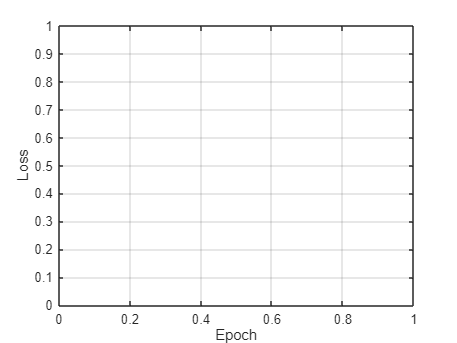

figure;
plot(loss_hist,'LineWidth',2);
xlabel('Epoch'); ylabel('Loss'); grid on;

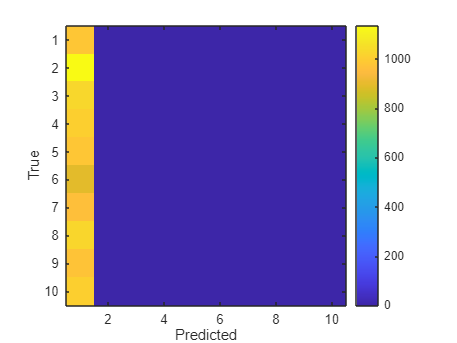

conf_mat = zeros(10,10);
for i=1:length(y_test)
    conf_mat(y_test(i)+1,pred(i)+1) = conf_mat(y_test(i)+1,pred(i)+1)+1;
end
figure;
imagesc(conf_mat);
colorbar;
xlabel('Predicted'); ylabel('True');
axis square;

# **Learning rate change to 1e-2**

d0 = 784; d1 = 128; d2 = 64; d3 = 10;
r1 = min(d1,d0);
r2 = min(d2,d1);
r3 = min(d3,d2);
rng(1);
[U1,~] = qr(randn(d1,r1),0);
[V1,~] = qr(randn(d0,r1),0);
alpha1 = randn(r1,1);
[U2,~] = qr(randn(d2,r2),0);
[V2,~] = qr(randn(d1,r2),0);
alpha2 = randn(r2,1);
[U3,~] = qr(randn(d3,r3),0);
[V3,~] = qr(randn(d2,r3),0);
alpha3 = randn(r3,1);

epochs = 100;
batch_size = 128;
lr = 1e-2;
lambda_orth = 1e-2;
lambda_sparse = 1e-3;
N = size(X_train,2);
num_batches = floor(N/batch_size);
loss_hist = zeros(epochs,1);

for epoch = 1:epochs
    perm = randperm(N);
    epoch_loss = 0;
    for b = 1:num_batches
        idx = perm((b-1)*batch_size+1 : b*batch_size);
        X = X_train(:,idx);
        Y = Y_train(:,idx);
        m = size(X,2);
        s1 = exp(alpha1);  S1 = diag(sqrt(s1));
        s2 = exp(alpha2);  S2 = diag(sqrt(s2));
        s3 = exp(alpha3);  S3 = diag(sqrt(s3));
        H1 = S1*(V1'*X);        Z1 = U1*S1*H1;  A1 = max(0,Z1);
        H2 = S2*(V2'*A1);       Z2 = U2*S2*H2;  A2 = max(0,Z2);
        H3 = S3*(V3'*A2);       Z3 = U3*S3*H3;
        Z3 = Z3 - max(Z3,[],1);
        Yhat = exp(Z3) ./ sum(exp(Z3),1);
        CE = -sum(sum(Y .* log(Yhat))) / m;
        Orth = ...
            norm(U1'*U1-eye(size(U1,2)),'fro')^2 + norm(V1'*V1-eye(size(V1,2)),'fro')^2 + ...
            norm(U2'*U2-eye(size(U2,2)),'fro')^2 + norm(V2'*V2-eye(size(V2,2)),'fro')^2 + ...
            norm(U3'*U3-eye(size(U3,2)),'fro')^2 + norm(V3'*V3-eye(size(V3,2)),'fro')^2;

        Sparse = norm(s1,1)/norm(s1,2) + norm(s2,1)/norm(s2,2) + norm(s3,1)/norm(s3,2);
        loss = CE + lambda_orth*Orth + lambda_sparse*Sparse;
        epoch_loss = epoch_loss + loss;
        dZ3 = Yhat - Y;
        dU3 = (dZ3*(S3*H3)')/m;
        dH3 = (U3*S3)'*dZ3;
        dV3 = (A2*(dH3'*S3))/m;
        ds3 = diag((U3'*dZ3)*H3')/m;
        dU3 = dU3 + 4*lambda_orth*U3*(U3'*U3-eye(size(U3,2)));
        dV3 = dV3 + 4*lambda_orth*V3*(V3'*V3-eye(size(V3,2)));
        ds3 = ds3 + lambda_sparse*( sign(s3)/norm(s3,2) - (norm(s3,1)/(norm(s3,2)^3))*s3 );
        dA2 = V3*(S3*dH3);     dZ2 = dA2 .* (Z2>0);
        dU2 = (dZ2*(S2*H2)')/m;
        dH2 = (U2*S2)'*dZ2;
        dV2 = (A1*(dH2'*S2))/m;
        ds2 = diag((U2'*dZ2)*H2')/m;
        dU2 = dU2 + 4*lambda_orth*U2*(U2'*U2-eye(size(U2,2)));
        dV2 = dV2 + 4*lambda_orth*V2*(V2'*V2-eye(size(V2,2)));
        ds2 = ds2 + lambda_sparse*( sign(s2)/norm(s2,2) - (norm(s2,1)/(norm(s2,2)^3))*s2 );
        dA1 = V2*(S2*dH2);     dZ1 = dA1 .* (Z1>0);
        dU1 = (dZ1*(S1*H1)')/m;
        dH1 = (U1*S1)'*dZ1;
        dV1 = (X*(dH1'*S1))/m;
        ds1 = diag((U1'*dZ1)*H1')/m;
        dU1 = dU1 + 4*lambda_orth*U1*(U1'*U1-eye(size(U1,2)));
        dV1 = dV1 + 4*lambda_orth*V1*(V1'*V1-eye(size(V1,2)));
        ds1 = ds1 + lambda_sparse*( sign(s1)/norm(s1,2) - (norm(s1,1)/(norm(s1,2)^3))*s1 );
        alpha1 = alpha1 - lr*(ds1.*s1);
        alpha2 = alpha2 - lr*(ds2.*s2);
        alpha3 = alpha3 - lr*(ds3.*s3);
        U1 = U1 - lr*dU1;  V1 = V1 - lr*dV1;
        U2 = U2 - lr*dU2;  V2 = V2 - lr*dV2;
        U3 = U3 - lr*dU3;  V3 = V3 - lr*dV3;
    end
    loss_hist(epoch) = epoch_loss/num_batches;
    fprintf('Epoch %d | Loss %.4f\n', epoch, loss_hist(epoch));
end

Epoch 1 | Loss 0.6082
Epoch 2 | Loss 0.3216
Epoch 3 | Loss 0.2649
Epoch 4 | Loss 0.2302
Epoch 5 | Loss 0.2060
Epoch 6 | Loss 0.1885
Epoch 7 | Loss 0.1731
Epoch 8 | Loss 0.1610
Epoch 9 | Loss 0.1515
Epoch 10 | Loss 0.1419
Epoch 11 | Loss 0.1343
Epoch 12 | Loss 0.1276
Epoch 13 | Loss 0.1220
Epoch 14 | Loss 0.1158
Epoch 15 | Loss 0.1115
Epoch 16 | Loss 0.1072
Epoch 17 | Loss 0.1032
Epoch 18 | Loss 0.0992
Epoch 19 | Loss 0.0956
Epoch 20 | Loss 0.0925
Epoch 21 | Loss 0.0887
Epoch 22 | Loss 0.0868
Epoch 23 | Loss 0.0822
Epoch 24 | Loss 0.0812
Epoch 25 | Loss 0.0782
Epoch 26 | Loss 0.0764
Epoch 27 | Loss 0.0732
Epoch 28 | Loss 0.0716
Epoch 29 | Loss 0.0693
Epoch 30 | Loss 0.0652
Epoch 31 | Loss 0.0646
Epoch 32 | Loss 0.0630
Epoch 33 | Loss 0.0623
Epoch 34 | Loss 0.0587
Epoch 35 | Loss 0.0571
Epoch 36 | Loss 0.0567
Epoch 37 | Loss 0.0549
Epoch 38 | Loss 0.0527
Epoch 39 | Loss 0.0508
Epoch 40 | Loss 0.0507
Epoch 41 | Loss 0.0500
Epoch 42 | Loss 0.0482
Epoch 43 | Loss 0.0478
Epoch 44 | Loss 0.04

energy_thresh = 0.99;
prune = @(s) find(cumsum(sort(s.^2,'descend'))/sum(s.^2) >= energy_thresh,1);
r1p = prune(exp(alpha1));
r2p = prune(exp(alpha2));
r3p = prune(exp(alpha3));
[~,i1] = sort(exp(alpha1),'descend');
[~,i2] = sort(exp(alpha2),'descend');
[~,i3] = sort(exp(alpha3),'descend');
U1 = U1(:,i1(1:r1p));  V1 = V1(:,i1(1:r1p));  alpha1 = alpha1(i1(1:r1p));
U2 = U2(:,i2(1:r2p));  V2 = V2(:,i2(1:r2p));  alpha2 = alpha2(i2(1:r2p));
U3 = U3(:,i3(1:r3p));  V3 = V3(:,i3(1:r3p));  alpha3 = alpha3(i3(1:r3p));

S1 = diag(sqrt(exp(alpha1)));
S2 = diag(sqrt(exp(alpha2)));
S3 = diag(sqrt(exp(alpha3)));
H1 = S1*(V1'*X_test);  A1 = max(0,U1*S1*H1);
H2 = S2*(V2'*A1);      A2 = max(0,U2*S2*H2);
H3 = S3*(V3'*A2);      Z3 = U3*S3*H3;
[~,pred] = max(Z3,[],1);
pred = pred - 1;
acc = mean(pred'==y_test)*100;
fprintf('Final Accuracy: %.2f%%\n', acc);

Final Accuracy: 9.80%


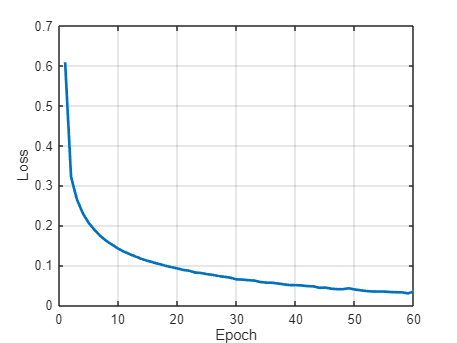

figure;
plot(loss_hist,'LineWidth',2);
xlabel('Epoch'); ylabel('Loss'); grid on;

conf_mat = zeros(10,10);
for i=1:length(y_test)
    conf_mat(y_test(i)+1,pred(i)+1) = conf_mat(y_test(i)+1,pred(i)+1)+1;
end
figure;
imagesc(conf_mat);
colorbar;
xlabel('Predicted'); ylabel('True');
axis square;

# **Learning rate change to 1e-3**

d0 = 784; d1 = 128; d2 = 64; d3 = 10;
r1 = min(d1,d0);
r2 = min(d2,d1);
r3 = min(d3,d2);
rng(1);
[U1,~] = qr(randn(d1,r1),0);
[V1,~] = qr(randn(d0,r1),0);
alpha1 = randn(r1,1);
[U2,~] = qr(randn(d2,r2),0);
[V2,~] = qr(randn(d1,r2),0);
alpha2 = randn(r2,1);
[U3,~] = qr(randn(d3,r3),0);
[V3,~] = qr(randn(d2,r3),0);
alpha3 = randn(r3,1);

epochs = 100;
batch_size = 128;
lr = 1e-3;
lambda_orth = 1e-2;
lambda_sparse = 1e-3;
N = size(X_train,2);
num_batches = floor(N/batch_size);
loss_hist = zeros(epochs,1);

for epoch = 1:epochs
    perm = randperm(N);
    epoch_loss = 0;
    for b = 1:num_batches
        idx = perm((b-1)*batch_size+1 : b*batch_size);
        X = X_train(:,idx);
        Y = Y_train(:,idx);
        m = size(X,2);
        s1 = exp(alpha1);  S1 = diag(sqrt(s1));
        s2 = exp(alpha2);  S2 = diag(sqrt(s2));
        s3 = exp(alpha3);  S3 = diag(sqrt(s3));
        H1 = S1*(V1'*X);        Z1 = U1*S1*H1;  A1 = max(0,Z1);
        H2 = S2*(V2'*A1);       Z2 = U2*S2*H2;  A2 = max(0,Z2);
        H3 = S3*(V3'*A2);       Z3 = U3*S3*H3;
        Z3 = Z3 - max(Z3,[],1);
        Yhat = exp(Z3) ./ sum(exp(Z3),1);
        CE = -sum(sum(Y .* log(Yhat))) / m;
        Orth = ...
            norm(U1'*U1-eye(size(U1,2)),'fro')^2 + norm(V1'*V1-eye(size(V1,2)),'fro')^2 + ...
            norm(U2'*U2-eye(size(U2,2)),'fro')^2 + norm(V2'*V2-eye(size(V2,2)),'fro')^2 + ...
            norm(U3'*U3-eye(size(U3,2)),'fro')^2 + norm(V3'*V3-eye(size(V3,2)),'fro')^2;

        Sparse = norm(s1,1)/norm(s1,2) + norm(s2,1)/norm(s2,2) + norm(s3,1)/norm(s3,2);
        loss = CE + lambda_orth*Orth + lambda_sparse*Sparse;
        epoch_loss = epoch_loss + loss;
        dZ3 = Yhat - Y;
        dU3 = (dZ3*(S3*H3)')/m;
        dH3 = (U3*S3)'*dZ3;
        dV3 = (A2*(dH3'*S3))/m;
        ds3 = diag((U3'*dZ3)*H3')/m;
        dU3 = dU3 + 4*lambda_orth*U3*(U3'*U3-eye(size(U3,2)));
        dV3 = dV3 + 4*lambda_orth*V3*(V3'*V3-eye(size(V3,2)));
        ds3 = ds3 + lambda_sparse*( sign(s3)/norm(s3,2) - (norm(s3,1)/(norm(s3,2)^3))*s3 );
        dA2 = V3*(S3*dH3);     dZ2 = dA2 .* (Z2>0);
        dU2 = (dZ2*(S2*H2)')/m;
        dH2 = (U2*S2)'*dZ2;
        dV2 = (A1*(dH2'*S2))/m;
        ds2 = diag((U2'*dZ2)*H2')/m;
        dU2 = dU2 + 4*lambda_orth*U2*(U2'*U2-eye(size(U2,2)));
        dV2 = dV2 + 4*lambda_orth*V2*(V2'*V2-eye(size(V2,2)));
        ds2 = ds2 + lambda_sparse*( sign(s2)/norm(s2,2) - (norm(s2,1)/(norm(s2,2)^3))*s2 );
        dA1 = V2*(S2*dH2);     dZ1 = dA1 .* (Z1>0);
        dU1 = (dZ1*(S1*H1)')/m;
        dH1 = (U1*S1)'*dZ1;
        dV1 = (X*(dH1'*S1))/m;
        ds1 = diag((U1'*dZ1)*H1')/m;
        dU1 = dU1 + 4*lambda_orth*U1*(U1'*U1-eye(size(U1,2)));
        dV1 = dV1 + 4*lambda_orth*V1*(V1'*V1-eye(size(V1,2)));
        ds1 = ds1 + lambda_sparse*( sign(s1)/norm(s1,2) - (norm(s1,1)/(norm(s1,2)^3))*s1 );
        alpha1 = alpha1 - lr*(ds1.*s1);
        alpha2 = alpha2 - lr*(ds2.*s2);
        alpha3 = alpha3 - lr*(ds3.*s3);
        U1 = U1 - lr*dU1;  V1 = V1 - lr*dV1;
        U2 = U2 - lr*dU2;  V2 = V2 - lr*dV2;
        U3 = U3 - lr*dU3;  V3 = V3 - lr*dV3;
    end
    loss_hist(epoch) = epoch_loss/num_batches;
    fprintf('Epoch %d | Loss %.4f\n', epoch, loss_hist(epoch));
end

Epoch 1 | Loss 1.3545
Epoch 2 | Loss 0.7574
Epoch 3 | Loss 0.5775
Epoch 4 | Loss 0.4890
Epoch 5 | Loss 0.4402
Epoch 6 | Loss 0.4083
Epoch 7 | Loss 0.3849
Epoch 8 | Loss 0.3669
Epoch 9 | Loss 0.3513
Epoch 10 | Loss 0.3382
Epoch 11 | Loss 0.3269
Epoch 12 | Loss 0.3177
Epoch 13 | Loss 0.3080
Epoch 14 | Loss 0.3002
Epoch 15 | Loss 0.2924
Epoch 16 | Loss 0.2860
Epoch 17 | Loss 0.2794
Epoch 18 | Loss 0.2732
Epoch 19 | Loss 0.2672
Epoch 20 | Loss 0.2621
Epoch 21 | Loss 0.2568
Epoch 22 | Loss 0.2522
Epoch 23 | Loss 0.2472
Epoch 24 | Loss 0.2425
Epoch 25 | Loss 0.2384
Epoch 26 | Loss 0.2347
Epoch 27 | Loss 0.2309
Epoch 28 | Loss 0.2269
Epoch 29 | Loss 0.2233
Epoch 30 | Loss 0.2198
Epoch 31 | Loss 0.2166
Epoch 32 | Loss 0.2133
Epoch 33 | Loss 0.2105
Epoch 34 | Loss 0.2077
Epoch 35 | Loss 0.2045
Epoch 36 | Loss 0.2017
Epoch 37 | Loss 0.1996
Epoch 38 | Loss 0.1967
Epoch 39 | Loss 0.1937
Epoch 40 | Loss 0.1920
Epoch 41 | Loss 0.1890
Epoch 42 | Loss 0.1868
Epoch 43 | Loss 0.1843
Epoch 44 | Loss 0.18

energy_thresh = 0.99;
prune = @(s) find(cumsum(sort(s.^2,'descend'))/sum(s.^2) >= energy_thresh,1);
r1p = prune(exp(alpha1));
r2p = prune(exp(alpha2));
r3p = prune(exp(alpha3));
[~,i1] = sort(exp(alpha1),'descend');
[~,i2] = sort(exp(alpha2),'descend');
[~,i3] = sort(exp(alpha3),'descend');
U1 = U1(:,i1(1:r1p));  V1 = V1(:,i1(1:r1p));  alpha1 = alpha1(i1(1:r1p));
U2 = U2(:,i2(1:r2p));  V2 = V2(:,i2(1:r2p));  alpha2 = alpha2(i2(1:r2p));
U3 = U3(:,i3(1:r3p));  V3 = V3(:,i3(1:r3p));  alpha3 = alpha3(i3(1:r3p));

S1 = diag(sqrt(exp(alpha1)));
S2 = diag(sqrt(exp(alpha2)));
S3 = diag(sqrt(exp(alpha3)));
H1 = S1*(V1'*X_test);  A1 = max(0,U1*S1*H1);
H2 = S2*(V2'*A1);      A2 = max(0,U2*S2*H2);
H3 = S3*(V3'*A2);      Z3 = U3*S3*H3;
[~,pred] = max(Z3,[],1);
pred = pred - 1;
acc = mean(pred'==y_test)*100;
fprintf('Final Accuracy: %.2f%%\n', acc);

Final Accuracy: 93.41%


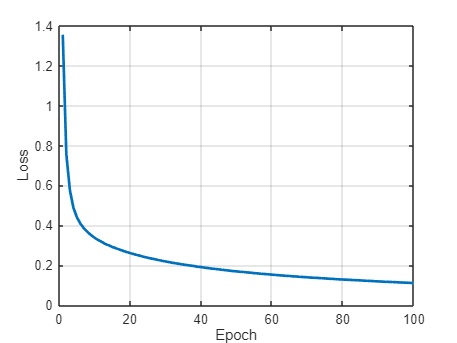

figure;
plot(loss_hist,'LineWidth',2);
xlabel('Epoch'); ylabel('Loss'); grid on;

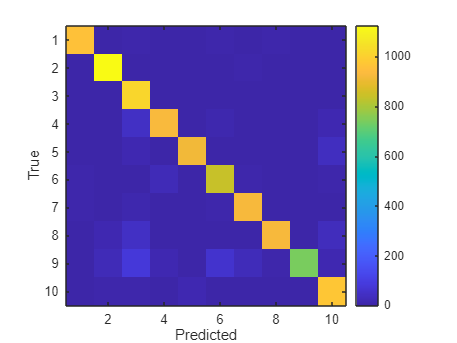

conf_mat = zeros(10,10);
for i=1:length(y_test)
    conf_mat(y_test(i)+1,pred(i)+1) = conf_mat(y_test(i)+1,pred(i)+1)+1;
end
figure;
imagesc(conf_mat);
colorbar;
xlabel('Predicted'); ylabel('True');
axis square;

# **Learning rate change to 1e-4**

d0 = 784; d1 = 128; d2 = 64; d3 = 10;
r1 = min(d1,d0);
r2 = min(d2,d1);
r3 = min(d3,d2);
rng(1);
[U1,~] = qr(randn(d1,r1),0);
[V1,~] = qr(randn(d0,r1),0);
alpha1 = randn(r1,1);
[U2,~] = qr(randn(d2,r2),0);
[V2,~] = qr(randn(d1,r2),0);
alpha2 = randn(r2,1);
[U3,~] = qr(randn(d3,r3),0);
[V3,~] = qr(randn(d2,r3),0);
alpha3 = randn(r3,1);

epochs = 100;
batch_size = 128;
lr = 1e-4;
lambda_orth = 1e-2;
lambda_sparse = 1e-3;
N = size(X_train,2);
num_batches = floor(N/batch_size);
loss_hist = zeros(epochs,1);

for epoch = 1:epochs
    perm = randperm(N);
    epoch_loss = 0;
    for b = 1:num_batches
        idx = perm((b-1)*batch_size+1 : b*batch_size);
        X = X_train(:,idx);
        Y = Y_train(:,idx);
        m = size(X,2);
        s1 = exp(alpha1);  S1 = diag(sqrt(s1));
        s2 = exp(alpha2);  S2 = diag(sqrt(s2));
        s3 = exp(alpha3);  S3 = diag(sqrt(s3));
        H1 = S1*(V1'*X);        Z1 = U1*S1*H1;  A1 = max(0,Z1);
        H2 = S2*(V2'*A1);       Z2 = U2*S2*H2;  A2 = max(0,Z2);
        H3 = S3*(V3'*A2);       Z3 = U3*S3*H3;
        Z3 = Z3 - max(Z3,[],1);
        Yhat = exp(Z3) ./ sum(exp(Z3),1);
        CE = -sum(sum(Y .* log(Yhat))) / m;
        Orth = ...
            norm(U1'*U1-eye(size(U1,2)),'fro')^2 + norm(V1'*V1-eye(size(V1,2)),'fro')^2 + ...
            norm(U2'*U2-eye(size(U2,2)),'fro')^2 + norm(V2'*V2-eye(size(V2,2)),'fro')^2 + ...
            norm(U3'*U3-eye(size(U3,2)),'fro')^2 + norm(V3'*V3-eye(size(V3,2)),'fro')^2;

        Sparse = norm(s1,1)/norm(s1,2) + norm(s2,1)/norm(s2,2) + norm(s3,1)/norm(s3,2);
        loss = CE + lambda_orth*Orth + lambda_sparse*Sparse;
        epoch_loss = epoch_loss + loss;
        dZ3 = Yhat - Y;
        dU3 = (dZ3*(S3*H3)')/m;
        dH3 = (U3*S3)'*dZ3;
        dV3 = (A2*(dH3'*S3))/m;
        ds3 = diag((U3'*dZ3)*H3')/m;
        dU3 = dU3 + 4*lambda_orth*U3*(U3'*U3-eye(size(U3,2)));
        dV3 = dV3 + 4*lambda_orth*V3*(V3'*V3-eye(size(V3,2)));
        ds3 = ds3 + lambda_sparse*( sign(s3)/norm(s3,2) - (norm(s3,1)/(norm(s3,2)^3))*s3 );
        dA2 = V3*(S3*dH3);     dZ2 = dA2 .* (Z2>0);
        dU2 = (dZ2*(S2*H2)')/m;
        dH2 = (U2*S2)'*dZ2;
        dV2 = (A1*(dH2'*S2))/m;
        ds2 = diag((U2'*dZ2)*H2')/m;
        dU2 = dU2 + 4*lambda_orth*U2*(U2'*U2-eye(size(U2,2)));
        dV2 = dV2 + 4*lambda_orth*V2*(V2'*V2-eye(size(V2,2)));
        ds2 = ds2 + lambda_sparse*( sign(s2)/norm(s2,2) - (norm(s2,1)/(norm(s2,2)^3))*s2 );
        dA1 = V2*(S2*dH2);     dZ1 = dA1 .* (Z1>0);
        dU1 = (dZ1*(S1*H1)')/m;
        dH1 = (U1*S1)'*dZ1;
        dV1 = (X*(dH1'*S1))/m;
        ds1 = diag((U1'*dZ1)*H1')/m;
        dU1 = dU1 + 4*lambda_orth*U1*(U1'*U1-eye(size(U1,2)));
        dV1 = dV1 + 4*lambda_orth*V1*(V1'*V1-eye(size(V1,2)));
        ds1 = ds1 + lambda_sparse*( sign(s1)/norm(s1,2) - (norm(s1,1)/(norm(s1,2)^3))*s1 );
        alpha1 = alpha1 - lr*(ds1.*s1);
        alpha2 = alpha2 - lr*(ds2.*s2);
        alpha3 = alpha3 - lr*(ds3.*s3);
        U1 = U1 - lr*dU1;  V1 = V1 - lr*dV1;
        U2 = U2 - lr*dU2;  V2 = V2 - lr*dV2;
        U3 = U3 - lr*dU3;  V3 = V3 - lr*dV3;
    end
    loss_hist(epoch) = epoch_loss/num_batches;
    fprintf('Epoch %d | Loss %.4f\n', epoch, loss_hist(epoch));
end

Epoch 1 | Loss 2.2176
Epoch 2 | Loss 1.8396
Epoch 3 | Loss 1.5982
Epoch 4 | Loss 1.4096
Epoch 5 | Loss 1.2668
Epoch 6 | Loss 1.1619
Epoch 7 | Loss 1.0816
Epoch 8 | Loss 1.0173
Epoch 9 | Loss 0.9639
Epoch 10 | Loss 0.9180
Epoch 11 | Loss 0.8780
Epoch 12 | Loss 0.8420
Epoch 13 | Loss 0.8101
Epoch 14 | Loss 0.7808
Epoch 15 | Loss 0.7539
Epoch 16 | Loss 0.7297
Epoch 17 | Loss 0.7066
Epoch 18 | Loss 0.6857
Epoch 19 | Loss 0.6660
Epoch 20 | Loss 0.6477
Epoch 21 | Loss 0.6303
Epoch 22 | Loss 0.6144
Epoch 23 | Loss 0.5993
Epoch 24 | Loss 0.5857
Epoch 25 | Loss 0.5729
Epoch 26 | Loss 0.5613
Epoch 27 | Loss 0.5502
Epoch 28 | Loss 0.5399
Epoch 29 | Loss 0.5307
Epoch 30 | Loss 0.5217
Epoch 31 | Loss 0.5132
Epoch 32 | Loss 0.5056
Epoch 33 | Loss 0.4983
Epoch 34 | Loss 0.4918
Epoch 35 | Loss 0.4850
Epoch 36 | Loss 0.4790
Epoch 37 | Loss 0.4738
Epoch 38 | Loss 0.4682
Epoch 39 | Loss 0.4628
Epoch 40 | Loss 0.4582
Epoch 41 | Loss 0.4534
Epoch 42 | Loss 0.4491
Epoch 43 | Loss 0.4445
Epoch 44 | Loss 0.44

energy_thresh = 0.99;
prune = @(s) find(cumsum(sort(s.^2,'descend'))/sum(s.^2) >= energy_thresh,1);
r1p = prune(exp(alpha1));
r2p = prune(exp(alpha2));
r3p = prune(exp(alpha3));
[~,i1] = sort(exp(alpha1),'descend');
[~,i2] = sort(exp(alpha2),'descend');
[~,i3] = sort(exp(alpha3),'descend');
U1 = U1(:,i1(1:r1p));  V1 = V1(:,i1(1:r1p));  alpha1 = alpha1(i1(1:r1p));
U2 = U2(:,i2(1:r2p));  V2 = V2(:,i2(1:r2p));  alpha2 = alpha2(i2(1:r2p));
U3 = U3(:,i3(1:r3p));  V3 = V3(:,i3(1:r3p));  alpha3 = alpha3(i3(1:r3p));

S1 = diag(sqrt(exp(alpha1)));
S2 = diag(sqrt(exp(alpha2)));
S3 = diag(sqrt(exp(alpha3)));
H1 = S1*(V1'*X_test);  A1 = max(0,U1*S1*H1);
H2 = S2*(V2'*A1);      A2 = max(0,U2*S2*H2);
H3 = S3*(V3'*A2);      Z3 = U3*S3*H3;
[~,pred] = max(Z3,[],1);
pred = pred - 1;
acc = mean(pred'==y_test)*100;
fprintf('Final Accuracy: %.2f%%\n', acc);

Final Accuracy: 87.14%


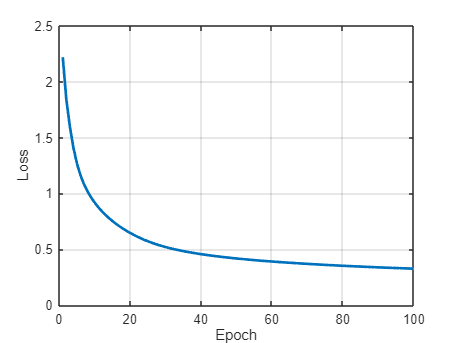

figure;
plot(loss_hist,'LineWidth',2);
xlabel('Epoch'); ylabel('Loss'); grid on;

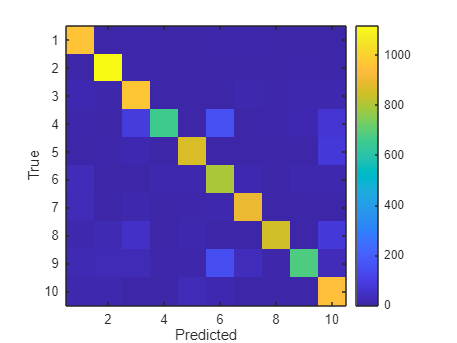

conf_mat = zeros(10,10);
for i=1:length(y_test)
    conf_mat(y_test(i)+1,pred(i)+1) = conf_mat(y_test(i)+1,pred(i)+1)+1;
end
figure;
imagesc(conf_mat);
colorbar;
xlabel('Predicted'); ylabel('True');
axis square;

# **Learning rate change to 1e-5**

d0 = 784; d1 = 128; d2 = 64; d3 = 10;
r1 = min(d1,d0);
r2 = min(d2,d1);
r3 = min(d3,d2);
rng(1);
[U1,~] = qr(randn(d1,r1),0);
[V1,~] = qr(randn(d0,r1),0);
alpha1 = randn(r1,1);
[U2,~] = qr(randn(d2,r2),0);
[V2,~] = qr(randn(d1,r2),0);
alpha2 = randn(r2,1);
[U3,~] = qr(randn(d3,r3),0);
[V3,~] = qr(randn(d2,r3),0);
alpha3 = randn(r3,1);

epochs = 100;
batch_size = 128;
lr = 1e-5;
lambda_orth = 1e-2;
lambda_sparse = 1e-3;
N = size(X_train,2);
num_batches = floor(N/batch_size);
loss_hist = zeros(epochs,1);

for epoch = 1:epochs
    perm = randperm(N);
    epoch_loss = 0;
    for b = 1:num_batches
        idx = perm((b-1)*batch_size+1 : b*batch_size);
        X = X_train(:,idx);
        Y = Y_train(:,idx);
        m = size(X,2);
        s1 = exp(alpha1);  S1 = diag(sqrt(s1));
        s2 = exp(alpha2);  S2 = diag(sqrt(s2));
        s3 = exp(alpha3);  S3 = diag(sqrt(s3));
        H1 = S1*(V1'*X);        Z1 = U1*S1*H1;  A1 = max(0,Z1);
        H2 = S2*(V2'*A1);       Z2 = U2*S2*H2;  A2 = max(0,Z2);
        H3 = S3*(V3'*A2);       Z3 = U3*S3*H3;
        Z3 = Z3 - max(Z3,[],1);
        Yhat = exp(Z3) ./ sum(exp(Z3),1);
        CE = -sum(sum(Y .* log(Yhat))) / m;
        Orth = ...
            norm(U1'*U1-eye(size(U1,2)),'fro')^2 + norm(V1'*V1-eye(size(V1,2)),'fro')^2 + ...
            norm(U2'*U2-eye(size(U2,2)),'fro')^2 + norm(V2'*V2-eye(size(V2,2)),'fro')^2 + ...
            norm(U3'*U3-eye(size(U3,2)),'fro')^2 + norm(V3'*V3-eye(size(V3,2)),'fro')^2;

        Sparse = norm(s1,1)/norm(s1,2) + norm(s2,1)/norm(s2,2) + norm(s3,1)/norm(s3,2);
        loss = CE + lambda_orth*Orth + lambda_sparse*Sparse;
        epoch_loss = epoch_loss + loss;
        dZ3 = Yhat - Y;
        dU3 = (dZ3*(S3*H3)')/m;
        dH3 = (U3*S3)'*dZ3;
        dV3 = (A2*(dH3'*S3))/m;
        ds3 = diag((U3'*dZ3)*H3')/m;
        dU3 = dU3 + 4*lambda_orth*U3*(U3'*U3-eye(size(U3,2)));
        dV3 = dV3 + 4*lambda_orth*V3*(V3'*V3-eye(size(V3,2)));
        ds3 = ds3 + lambda_sparse*( sign(s3)/norm(s3,2) - (norm(s3,1)/(norm(s3,2)^3))*s3 );
        dA2 = V3*(S3*dH3);     dZ2 = dA2 .* (Z2>0);
        dU2 = (dZ2*(S2*H2)')/m;
        dH2 = (U2*S2)'*dZ2;
        dV2 = (A1*(dH2'*S2))/m;
        ds2 = diag((U2'*dZ2)*H2')/m;
        dU2 = dU2 + 4*lambda_orth*U2*(U2'*U2-eye(size(U2,2)));
        dV2 = dV2 + 4*lambda_orth*V2*(V2'*V2-eye(size(V2,2)));
        ds2 = ds2 + lambda_sparse*( sign(s2)/norm(s2,2) - (norm(s2,1)/(norm(s2,2)^3))*s2 );
        dA1 = V2*(S2*dH2);     dZ1 = dA1 .* (Z1>0);
        dU1 = (dZ1*(S1*H1)')/m;
        dH1 = (U1*S1)'*dZ1;
        dV1 = (X*(dH1'*S1))/m;
        ds1 = diag((U1'*dZ1)*H1')/m;
        dU1 = dU1 + 4*lambda_orth*U1*(U1'*U1-eye(size(U1,2)));
        dV1 = dV1 + 4*lambda_orth*V1*(V1'*V1-eye(size(V1,2)));
        ds1 = ds1 + lambda_sparse*( sign(s1)/norm(s1,2) - (norm(s1,1)/(norm(s1,2)^3))*s1 );
        alpha1 = alpha1 - lr*(ds1.*s1);
        alpha2 = alpha2 - lr*(ds2.*s2);
        alpha3 = alpha3 - lr*(ds3.*s3);
        U1 = U1 - lr*dU1;  V1 = V1 - lr*dV1;
        U2 = U2 - lr*dU2;  V2 = V2 - lr*dV2;
        U3 = U3 - lr*dU3;  V3 = V3 - lr*dV3;
    end
    loss_hist(epoch) = epoch_loss/num_batches;
    fprintf('Epoch %d | Loss %.4f\n', epoch, loss_hist(epoch));
end

Epoch 1 | Loss 2.5923
Epoch 2 | Loss 2.4255
Epoch 3 | Loss 2.3308
Epoch 4 | Loss 2.2615
Epoch 5 | Loss 2.2039
Epoch 6 | Loss 2.1542
Epoch 7 | Loss 2.1102
Epoch 8 | Loss 2.0704
Epoch 9 | Loss 2.0339
Epoch 10 | Loss 1.9995
Epoch 11 | Loss 1.9672
Epoch 12 | Loss 1.9360
Epoch 13 | Loss 1.9064
Epoch 14 | Loss 1.8775
Epoch 15 | Loss 1.8496
Epoch 16 | Loss 1.8226
Epoch 17 | Loss 1.7959
Epoch 18 | Loss 1.7701
Epoch 19 | Loss 1.7450
Epoch 20 | Loss 1.7205
Epoch 21 | Loss 1.6964
Epoch 22 | Loss 1.6730
Epoch 23 | Loss 1.6502
Epoch 24 | Loss 1.6276
Epoch 25 | Loss 1.6062
Epoch 26 | Loss 1.5851
Epoch 27 | Loss 1.5639
Epoch 28 | Loss 1.5438
Epoch 29 | Loss 1.5240
Epoch 30 | Loss 1.5050
Epoch 31 | Loss 1.4858
Epoch 32 | Loss 1.4674
Epoch 33 | Loss 1.4496
Epoch 34 | Loss 1.4323
Epoch 35 | Loss 1.4151
Epoch 36 | Loss 1.3987
Epoch 37 | Loss 1.3829
Epoch 38 | Loss 1.3672
Epoch 39 | Loss 1.3521
Epoch 40 | Loss 1.3376
Epoch 41 | Loss 1.3234
Epoch 42 | Loss 1.3099
Epoch 43 | Loss 1.2964
Epoch 44 | Loss 1.28

energy_thresh = 0.99;
prune = @(s) find(cumsum(sort(s.^2,'descend'))/sum(s.^2) >= energy_thresh,1);
r1p = prune(exp(alpha1));
r2p = prune(exp(alpha2));
r3p = prune(exp(alpha3));
[~,i1] = sort(exp(alpha1),'descend');
[~,i2] = sort(exp(alpha2),'descend');
[~,i3] = sort(exp(alpha3),'descend');
U1 = U1(:,i1(1:r1p));  V1 = V1(:,i1(1:r1p));  alpha1 = alpha1(i1(1:r1p));
U2 = U2(:,i2(1:r2p));  V2 = V2(:,i2(1:r2p));  alpha2 = alpha2(i2(1:r2p));
U3 = U3(:,i3(1:r3p));  V3 = V3(:,i3(1:r3p));  alpha3 = alpha3(i3(1:r3p));

S1 = diag(sqrt(exp(alpha1)));
S2 = diag(sqrt(exp(alpha2)));
S3 = diag(sqrt(exp(alpha3)));
H1 = S1*(V1'*X_test);  A1 = max(0,U1*S1*H1);
H2 = S2*(V2'*A1);      A2 = max(0,U2*S2*H2);
H3 = S3*(V3'*A2);      Z3 = U3*S3*H3;
[~,pred] = max(Z3,[],1);
pred = pred - 1;
acc = mean(pred'==y_test)*100;
fprintf('Final Accuracy: %.2f%%\n', acc);

Final Accuracy: 64.26%


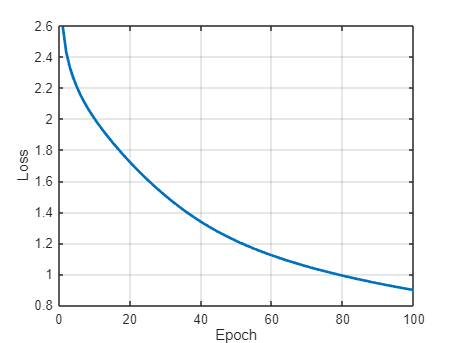

figure;
plot(loss_hist,'LineWidth',2);
xlabel('Epoch'); ylabel('Loss'); grid on;

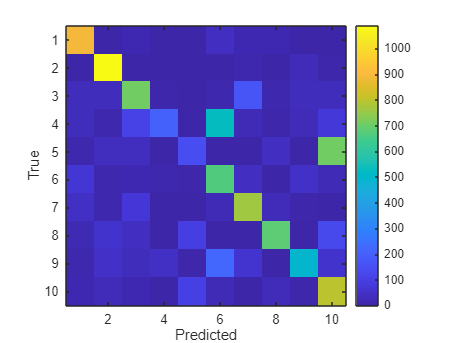

conf_mat = zeros(10,10);
for i=1:length(y_test)
    conf_mat(y_test(i)+1,pred(i)+1) = conf_mat(y_test(i)+1,pred(i)+1)+1;
end
figure;
imagesc(conf_mat);
colorbar;
xlabel('Predicted'); ylabel('True');
axis square;

# **Learning rate change to 1e-6**

d0 = 784; d1 = 128; d2 = 64; d3 = 10;
r1 = min(d1,d0);
r2 = min(d2,d1);
r3 = min(d3,d2);
rng(1);
[U1,~] = qr(randn(d1,r1),0);
[V1,~] = qr(randn(d0,r1),0);
alpha1 = randn(r1,1);
[U2,~] = qr(randn(d2,r2),0);
[V2,~] = qr(randn(d1,r2),0);
alpha2 = randn(r2,1);
[U3,~] = qr(randn(d3,r3),0);
[V3,~] = qr(randn(d2,r3),0);
alpha3 = randn(r3,1);

epochs = 100;
batch_size = 128;
lr = 1e-6;
lambda_orth = 1e-2;
lambda_sparse = 1e-3;
N = size(X_train,2);
num_batches = floor(N/batch_size);
loss_hist = zeros(epochs,1);

for epoch = 1:epochs
    perm = randperm(N);
    epoch_loss = 0;
    for b = 1:num_batches
        idx = perm((b-1)*batch_size+1 : b*batch_size);
        X = X_train(:,idx);
        Y = Y_train(:,idx);
        m = size(X,2);
        s1 = exp(alpha1);  S1 = diag(sqrt(s1));
        s2 = exp(alpha2);  S2 = diag(sqrt(s2));
        s3 = exp(alpha3);  S3 = diag(sqrt(s3));
        H1 = S1*(V1'*X);        Z1 = U1*S1*H1;  A1 = max(0,Z1);
        H2 = S2*(V2'*A1);       Z2 = U2*S2*H2;  A2 = max(0,Z2);
        H3 = S3*(V3'*A2);       Z3 = U3*S3*H3;
        Z3 = Z3 - max(Z3,[],1);
        Yhat = exp(Z3) ./ sum(exp(Z3),1);
        CE = -sum(sum(Y .* log(Yhat))) / m;
        Orth = ...
            norm(U1'*U1-eye(size(U1,2)),'fro')^2 + norm(V1'*V1-eye(size(V1,2)),'fro')^2 + ...
            norm(U2'*U2-eye(size(U2,2)),'fro')^2 + norm(V2'*V2-eye(size(V2,2)),'fro')^2 + ...
            norm(U3'*U3-eye(size(U3,2)),'fro')^2 + norm(V3'*V3-eye(size(V3,2)),'fro')^2;

        Sparse = norm(s1,1)/norm(s1,2) + norm(s2,1)/norm(s2,2) + norm(s3,1)/norm(s3,2);
        loss = CE + lambda_orth*Orth + lambda_sparse*Sparse;
        epoch_loss = epoch_loss + loss;
        dZ3 = Yhat - Y;
        dU3 = (dZ3*(S3*H3)')/m;
        dH3 = (U3*S3)'*dZ3;
        dV3 = (A2*(dH3'*S3))/m;
        ds3 = diag((U3'*dZ3)*H3')/m;
        dU3 = dU3 + 4*lambda_orth*U3*(U3'*U3-eye(size(U3,2)));
        dV3 = dV3 + 4*lambda_orth*V3*(V3'*V3-eye(size(V3,2)));
        ds3 = ds3 + lambda_sparse*( sign(s3)/norm(s3,2) - (norm(s3,1)/(norm(s3,2)^3))*s3 );
        dA2 = V3*(S3*dH3);     dZ2 = dA2 .* (Z2>0);
        dU2 = (dZ2*(S2*H2)')/m;
        dH2 = (U2*S2)'*dZ2;
        dV2 = (A1*(dH2'*S2))/m;
        ds2 = diag((U2'*dZ2)*H2')/m;
        dU2 = dU2 + 4*lambda_orth*U2*(U2'*U2-eye(size(U2,2)));
        dV2 = dV2 + 4*lambda_orth*V2*(V2'*V2-eye(size(V2,2)));
        ds2 = ds2 + lambda_sparse*( sign(s2)/norm(s2,2) - (norm(s2,1)/(norm(s2,2)^3))*s2 );
        dA1 = V2*(S2*dH2);     dZ1 = dA1 .* (Z1>0);
        dU1 = (dZ1*(S1*H1)')/m;
        dH1 = (U1*S1)'*dZ1;
        dV1 = (X*(dH1'*S1))/m;
        ds1 = diag((U1'*dZ1)*H1')/m;
        dU1 = dU1 + 4*lambda_orth*U1*(U1'*U1-eye(size(U1,2)));
        dV1 = dV1 + 4*lambda_orth*V1*(V1'*V1-eye(size(V1,2)));
        ds1 = ds1 + lambda_sparse*( sign(s1)/norm(s1,2) - (norm(s1,1)/(norm(s1,2)^3))*s1 );
        alpha1 = alpha1 - lr*(ds1.*s1);
        alpha2 = alpha2 - lr*(ds2.*s2);
        alpha3 = alpha3 - lr*(ds3.*s3);
        U1 = U1 - lr*dU1;  V1 = V1 - lr*dV1;
        U2 = U2 - lr*dU2;  V2 = V2 - lr*dV2;
        U3 = U3 - lr*dU3;  V3 = V3 - lr*dV3;
    end
    loss_hist(epoch) = epoch_loss/num_batches;
    fprintf('Epoch %d | Loss %.4f\n', epoch, loss_hist(epoch));
end

Epoch 1 | Loss 2.7149
Epoch 2 | Loss 2.6797
Epoch 3 | Loss 2.6480
Epoch 4 | Loss 2.6202
Epoch 5 | Loss 2.5946
Epoch 6 | Loss 2.5716
Epoch 7 | Loss 2.5503
Epoch 8 | Loss 2.5310
Epoch 9 | Loss 2.5131
Epoch 10 | Loss 2.4964
Epoch 11 | Loss 2.4809
Epoch 12 | Loss 2.4664
Epoch 13 | Loss 2.4533
Epoch 14 | Loss 2.4405
Epoch 15 | Loss 2.4283
Epoch 16 | Loss 2.4172
Epoch 17 | Loss 2.4063
Epoch 18 | Loss 2.3958
Epoch 19 | Loss 2.3860
Epoch 20 | Loss 2.3764
Epoch 21 | Loss 2.3672
Epoch 22 | Loss 2.3586
Epoch 23 | Loss 2.3501
Epoch 24 | Loss 2.3416
Epoch 25 | Loss 2.3337
Epoch 26 | Loss 2.3259
Epoch 27 | Loss 2.3182
Epoch 28 | Loss 2.3109
Epoch 29 | Loss 2.3039
Epoch 30 | Loss 2.2969
Epoch 31 | Loss 2.2899
Epoch 32 | Loss 2.2833
Epoch 33 | Loss 2.2768
Epoch 34 | Loss 2.2704
Epoch 35 | Loss 2.2640
Epoch 36 | Loss 2.2577
Epoch 37 | Loss 2.2518
Epoch 38 | Loss 2.2456
Epoch 39 | Loss 2.2397
Epoch 40 | Loss 2.2338
Epoch 41 | Loss 2.2282
Epoch 42 | Loss 2.2226
Epoch 43 | Loss 2.2170
Epoch 44 | Loss 2.21

energy_thresh = 0.99;
prune = @(s) find(cumsum(sort(s.^2,'descend'))/sum(s.^2) >= energy_thresh,1);
r1p = prune(exp(alpha1));
r2p = prune(exp(alpha2));
r3p = prune(exp(alpha3));
[~,i1] = sort(exp(alpha1),'descend');
[~,i2] = sort(exp(alpha2),'descend');
[~,i3] = sort(exp(alpha3),'descend');
U1 = U1(:,i1(1:r1p));  V1 = V1(:,i1(1:r1p));  alpha1 = alpha1(i1(1:r1p));
U2 = U2(:,i2(1:r2p));  V2 = V2(:,i2(1:r2p));  alpha2 = alpha2(i2(1:r2p));
U3 = U3(:,i3(1:r3p));  V3 = V3(:,i3(1:r3p));  alpha3 = alpha3(i3(1:r3p));

S1 = diag(sqrt(exp(alpha1)));
S2 = diag(sqrt(exp(alpha2)));
S3 = diag(sqrt(exp(alpha3)));
H1 = S1*(V1'*X_test);  A1 = max(0,U1*S1*H1);
H2 = S2*(V2'*A1);      A2 = max(0,U2*S2*H2);
H3 = S3*(V3'*A2);      Z3 = U3*S3*H3;
[~,pred] = max(Z3,[],1);
pred = pred - 1;
acc = mean(pred'==y_test)*100;
fprintf('Final Accuracy: %.2f%%\n', acc);

Final Accuracy: 31.82%


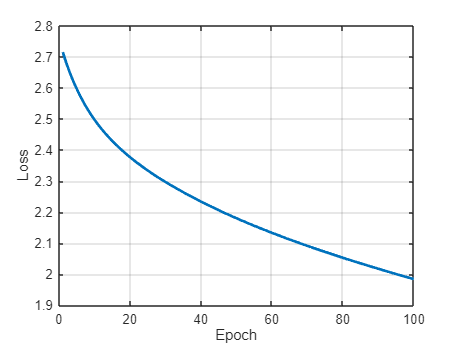

figure;
plot(loss_hist,'LineWidth',2);
xlabel('Epoch'); ylabel('Loss'); grid on;

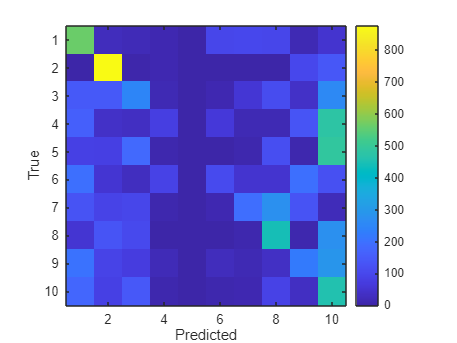

conf_mat = zeros(10,10);
for i=1:length(y_test)
    conf_mat(y_test(i)+1,pred(i)+1) = conf_mat(y_test(i)+1,pred(i)+1)+1;
end
figure;
imagesc(conf_mat);
colorbar;
xlabel('Predicted'); ylabel('True');
axis square;